%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 158356*0.946

W = 1.4980e+05


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.10

PerLamFlow = 0.1000

CLDMin = 0.1

CLDMin = 0.1000


%Planform Parameters
S = 1693; %ft^2
AR = 8.23

AR = 8.2300

%AR2 = 5.23
%b2=100
TaperRatio = 0.4;
b = 118

b = 118

Q = 1.01

Q = 1.0100

SweepQuartC = 0;

%Fuselage Parameters
Df = 15.5; %ft
LNose = 16; %ft
LMid = 44; %ft
LTail = 37.3 %ft

LTail = 37.3000

DBase = 4 %ft

DBase = 4

ABase = pi*DBase^2/4

ABase = 12.5664

UpsweepAngle = atan((Df/2-DBase/2)/LTail); %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300*2; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


%Nacelle Parameters
LNacelle = 78/12;
DNacelle = 34/12;

%Blister Parameters
LBlister = 16;
DBlister = 3;

%Induced Drag Factor

Ne = 0; %Num of engines ON TOP of Wing
TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)

TaperFunc = 0.0053

K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)

K = 0.0468

e = 1/(K*AR*pi)

e = 0.8258


[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 997.2704

M = 0.9820

Cr = 20.4964

Cmac = 15.2259

Ymac = 25.2857

SweepMaxT = -1.7896

Sexp = 1.3878e+03

Re = 8.4781e+07

SweepMaxT = -1.7896

Cf = 0.0021

FF = 1.7035

Swet = 2.8520e+03

CDo = 0.0062


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 997.2704

M = 0.9820

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Sexp = 400

Re = 4.7348e+07

SweepMaxT = -1.7183

Cf = 0.0023

FF = 1.6379

Swet = 815.7600

CDo = 0.0082


CDoHt = CDoHt*Sh/S

CDoHt = 0.0019


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 997.2704

M = 0.9820

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Sexp = 600

Re = 5.2812e+07

SweepMaxT = -0.9437

Cf = 0.0023

FF = 1.6380

Swet = 1.2236e+03

CDo = 0.0080


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0014


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

Cf = 0.0018

FF = 1.2582

SWet = 4.0346e+03

CDo = 0.0054

CDoFuse = 0.0054


[CDoNacelle] = 8*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S)

Cf = 0.0024

FF = 1.1526

SWet = 57.8577

CDo = 1.4439e-04

CDoNacelle = 0.0012


[CDoBlisters] = ParaDragNacelle(h,V,LBlister,DBlister,DynVisc,S)

Cf = 0.0021

FF = 1.0656

SWet = 150.7964

CDo = 3.0188e-04

CDoBlisters = 3.0188e-04


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0039


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0022


BaseDrag = (0.1+0.1222*M^8)*ABase/S

BaseDrag = 7.5415e-04


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber

CDoTotal = 0.0230





CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2;
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

LDMax = 0.4349

LDMax = 0.8692

LDMax = 1.3025

LDMax = 1.7342

LDMax = 2.1638

LDMax = 2.5907

LDMax = 3.0146

LDMax = 3.4349

LDMax = 3.8511

LDMax = 4.2627

LDMax = 4.6694

LDMax = 5.0707

LDMax = 5.4662

LDMax = 5.8556

LDMax = 6.2384

LDMax = 6.6144

LDMax = 6.9831

LDMax = 7.3445

LDMax = 7.6980

LDMax = 8.0437

LDMax = 8.3811

LDMax = 8.7102

LDMax = 9.0308

LDMax = 9.3427

LDMax = 9.6458

LDMax = 9.9400

LDMax = 10.2253

LDMax = 10.5015

LDMax = 10.7688

LDMax = 11.0270

LDMax = 11.2761

LDMax = 11.5162

LDMax = 11.7474

LDMax = 11.9697

LDMax = 12.1831

LDMax = 12.3878

LDMax = 12.5839

LDMax = 12.7714

LDMax = 12.9505

LDMax = 13.1214

LDMax = 13.2841

LDMax = 13.4388

LDMax = 13.5858

LDMax = 13.7250

LDMax = 13.8568

LDMax = 13.9812

LDMax = 14.0985

LDMax = 14.2088

LDMax = 14.3124

LDMax = 14.4093

LDMax = 14.4998

LDMax = 14.5841

LDMax = 14.6623

LDMax = 14.7347

LDMax = 14.8014

LDMax = 14.8625

LDMax = 14.9184

LDMax = 14.9691

LDMax = 15.0148

LDMax = 15.0558

LDMax = 15.0921

LDMax = 15.1239

LDMax = 15.1515

LDMax = 15.1749

LDMax = 15.1944

LDMax = 15.2100

LDMax = 15.2219

LDMax = 15.2303

LDMax = 15.2353

LDMax = 15.2371


% K2 = 1/(0.987*pi*AR)
% 
% LDMax2 = 0;
% 
% for x=1:201
%     
%    CD2(x) = CDoTotal2 + K2*CL(x)^2;
%    
%    if CL(x)/CD(x)>LDMax2
%        
%        LDMax2 = CL(x)/CD2(x)
%        
%    end
%    
% end

plot (CD,CL)

xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on
grid minor
hold on
LDMax

LDMax = 15.2371


DynViscSL = 3.737*10^(-7)

DynViscSL = 3.7370e-07

Swf = 1100

Swf = 1100

%%%%%%%%%%%%%%%%%%%%%
% Landing and Takeoff
%%%%%%%%%%%%%%%%%%%%%

[CDoWingSL] = WingZeroLiftDrag(100,Q,TaperRatio,DynViscSL,0,S,AR,b,0,LocMaxT,Df,PerLamFlow,Tmax);

V = 168.8000

M = 0.1513

Cr = 20.4964

Cmac = 15.2259

Ymac = 25.2857

SweepMaxT = -1.7896

Sexp = 1.3878e+03

Re = 2.7594e+07

SweepMaxT = -1.7896

Cf = 0.0023

FF = 1.2165

Swet = 2.8520e+03

CDo = 0.0048


[CDoHtSL] = WingZeroLiftDrag(100,QHt,TaperRatioh,DynViscSL,0,Sh,ARh,bh,0,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 168.8000

M = 0.1513

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Sexp = 400

Re = 1.5411e+07

SweepMaxT = -1.7183

Cf = 0.0026

FF = 1.1696

Swet = 815.7600

CDo = 0.0064


CDoHtSL = CDoHtSL*Sh/S

CDoHtSL = 0.0015


[CDoVtSL] = WingZeroLiftDrag(100,QVt,TaperRatiov,DynViscSL,0,Sv,ARv,bv,0,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 168.8000

M = 0.1513

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Sexp = 600

Re = 1.7189e+07

SweepMaxT = -0.9437

Cf = 0.0025

FF = 1.1697

Swet = 1.2236e+03

CDo = 0.0063


CDoVtSL = CDoVtSL*Sv/S/2

CDoVtSL = 0.0011


[CDoFuseSL] = ParaDragFuse(0,100,LMid,LNose,LTail,Df,DynViscSL,S)

Cf = 0.0021

FF = 1.2582

SWet = 4.0346e+03

CDo = 0.0063

CDoFuseSL = 0.0063


[CDoNacelleSL] = 8*ParaDragNacelle(0,100,LNacelle,DNacelle,DynViscSL,S)

Cf = 0.0029

FF = 1.1526

SWet = 57.8577

CDo = 1.7191e-04

CDoNacelleSL = 0.0014


[CDoBlistersSL] = ParaDragNacelle(0,100,LBlister,DBlister,DynViscSL,S)

Cf = 0.0025

FF = 1.0656

SWet = 150.7964

CDo = 3.5726e-04

CDoBlistersSL = 3.5726e-04


CDo_CleanSL = CDoWingSL + CDoHtSL + CDoVtSL + CDoFuseSL + UpSweepDrag + BaseDrag + CDoNacelleSL + CDoCamber

CDo_CleanSL = 0.0220


k1 = 1.75

k1 = 1.7500


k2Landing = 0.0375

k2Landing = 0.0375


k2TO = 0.0125

k2TO = 0.0125


dCDoLanding = k1*k2Landing*Swf/S

dCDoLanding = 0.0426


dCDoTO = k1*k2TO*Swf/S

dCDoTO = 0.0142

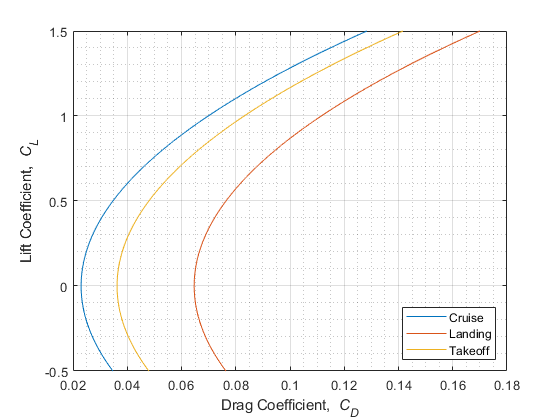


for x=1:201
    
   CDLanding(x) = CDo_CleanSL+dCDoLanding + K*CL(x)^2;

   CDTO(x) = CDo_CleanSL+dCDoTO + K*CL(x)^2;
    
end



plot (CDLanding,CL)
plot (CDTO,CL)

legend('Cruise','Landing', 'Takeoff')
legend('Location','southeast')

hold off